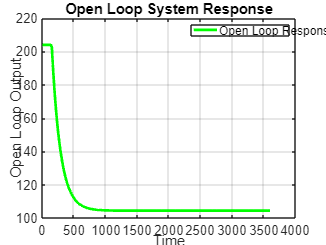

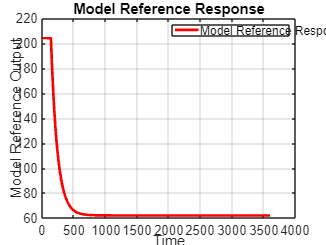

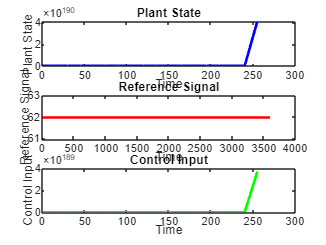

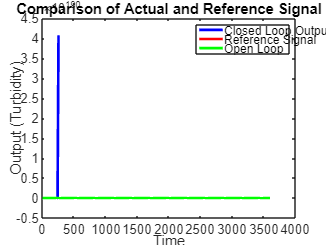

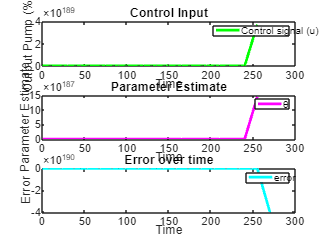

% Model_12_100
% Define parameters
k = 99.60885347;    % Value of 'k'

tau = 135.9927555;    % Value of 'tau'
% k = 1.5614;    % Value of 'k'
% tau = 3293.2;    % Value of 'tau'

% Time span
tspan = 0:15:3600;
dt = 15;

% Define control input function (example: step function)
u = @(tspan) 1 * (tspan >= 1);  % Step function at t = 1

% Initial condition
x0 = 203.97;     % Initial value of x

% Define the differential equation function
f1 = @(tspan, x) -1/tau *(x-x0) - k/tau * u(tspan);

% Solve the differential equation
[~, x1] = ode45(f1, tspan, x0);

% Plot the open-loop response
figure;
plot(tspan, x1, 'g', 'LineWidth', 2);
xlabel('Time');
ylabel('Open Loop Output');
title('Open Loop System Response');
legend('Open Loop Response');
grid on;

% MRAC Control
% Define system parameters
k_m = 142;         % Value of 'k' for the reference model
tau_m = 101.801862; % Value of 'tau' for the reference model

% Parameters
am = -1/tau_m % Reference model parameter
bm = -k_m/tau_m % Reference model parameter
% am = 0.0015; % Reference model parameter
% bm = 0.001;  % Reference model parameter
a = -1/tau;   % Plant parameter
b = -k/tau;   % Plant parameter
gamma = 1e-06; % Adaptation rate

% Control gains
kx = (am - a)/b
kr = bm/b

% Simulation parameters
dt = 15; % Time step
t_end = 3600; % Simulation time

% Reference signal
t = 0:dt:t_end;

% Define the differential equation function for reference model
f2 = @(t, xm) -1/tau_m * (xm - x0 + k_m);

% Solve the differential equation for reference model
[~, xm] = ode45(f2, t, x0);
r = xm;

% Plot the reference model response
figure;
plot(tspan, r, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Model Reference Output');
title('Model Reference Response');
legend('Model Reference Response');
grid on;

% Initialize variables
x_cl = zeros(size(t));  % Plant state
x_cl(1) = 203.97; % initial condition
theta = zeros(size(t));  % Parameter estimate
theta(1) = 0.; % initial guess
u = zeros(size(t));  % Control input
error = zeros(size(t));  % Control input

% Main loop
for i = 2:length(t)
    % Error
    e = r(i) - x(i-1);
    error(i) = e;
    
    % Control law
    u(i) = kx * x_cl(i-1) + kr * r(i) - theta(i-1) * x_cl(i-1);

    % Limit control input to the range [0, 100]
    u(i) = min(max(u(i), 40), 100);
    
    % Update plant state
    x_cl(i) = x_cl(i-1) + dt * (a * (x_cl(i-1) + b * u(i)));
    
    % Adaptation law
    theta_dot = -gamma * e * x(i-1);
    theta(i) = theta(i-1) + dt * theta_dot;
end

% Plot results
figure;
subplot(3,1,1);
plot(t, x, 'b', 'LineWidth', 2);
xlabel('Time');
ylabel('Plant State');
title('Plant State');

subplot(3,1,2);
plot(t, r, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Reference Signal');
title('Reference Signal');

subplot(3,1,3);
plot(t, u, 'g', 'LineWidth', 2);
xlabel('Time');
ylabel('Control Input');
title('Control Input');

% Plot results
figure;
plot(t, x, 'b', t, r, 'r','LineWidth', 2);
hold on
plot(t,x1,'g','LineWidth', 2)
hold off
xlabel('Time');
ylabel('Output (Turbidity)');
legend('Close Loop Output', 'Reference Signal','Open Loop');
title('Comparison of Actual and Reference Signal');

figure;
subplot(3,1,1)
plot(t,u, 'g', 'LineWidth', 2);
xlabel('Time');
legend('Control signal (u)')
ylabel('Output Pump (%)');
title('Control Input');

subplot(3,1,2)
plot(t, theta, 'm', 'LineWidth', 2);
xlabel('Time');
legend('θ')
ylabel('Parameter Estimate');
title('Parameter Estimate');

subplot(3,1,3)
plot(t, error, 'c', 'LineWidth', 2);
xlabel('Time');
legend('error')
ylabel('Error');
title('Error over time');
